# Implicit Deep Learning Tutorial on Synthetic Data

The impicit prediction rule reads


$$y=Ax+Bu+c\\
x=\phi(Dx+Eu+f)$$


we consider the well-posedness condition $\|D\|_\infty <1$. We consider the following dimensions $x\in R^h$, $u \in R^n$, $y \in R^p$ with matrices and vectors $A, B, c, D, E, f$ of corresponding appropriate dimensions. 

Let us start by drawing the real weights for the implicit model

n=10; h=100; p=5; density=0.3;
A=sprand(p,h,density).*(sign(rand(p,h)-0.5)); B=sprand(p,n,density).*(sign(rand(p,n)-0.5)); c=rand(p,1)-0.5;
D=sprand(h,h,density).*(sign(rand(h,h)-0.5)); E=sprand(h,n,density).*(sign(rand(h,n)-0.5)); f=rand(h,1)-0.5;
% project D to make it well-posed
funcs=UtilitiesIDL;
D=funcs.infty_norm_projection(D,0.1);

We denote $m$ the number of datapoints, we create our synthetic datatset. We consider that $u \sim \mathcal{N}(0,\Sigma_{\text{train}})$, where $\Sigma_{\text{train}}$ is a covariance matrix

Mat=funcs.RandOrthMat(n); Sigma_train=Mat'*diag(n*rand(n,1))*Mat; clear Mat;
% num of datapoint
m=10^3;
U = mvnrnd(zeros(n,1),Sigma_train,m)'; clear Sigma_train;
% find corresponding X using Picard iterations
X=funcs.picard_iterations(U,D,E,f, 'leakyReLU');
Y=A*X+B*U+c*ones(1,m);

## (1) Training Using the Implicit Model

num_iter = 1;
radius = 0.5;
idl=ImplicitDeepLearning(U, Y, h, num_iter, 0 , radius); 
tic; 
idl=idl.train;
disp(toc)

    0.1184



## (2) Linear model fit for comparison

We solve the following convex optimization problem instead (as a comparison)


$$\min_{B_{lin},c_{lin}}\|B_{lin}U+c_{lin}-Y\|_F$$


cvx_begin 
variable B_lin(p,n) 
variable c_lin(p,1)
minimize((1/sqrt(m))*norm(B_lin*U+c_lin*ones(1,m)-Y,'fro'))
cvx_end

 
Calling SDPT3 4.0: 5001 variables, 56 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 56
 dim. of socp   var  = 5001,   num. of socp blk  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|6.9e+01|1.4e+00|2.4e+04| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.975|1.000|1.7e+00|3.0e-04|6.2e+02|-7.555275e-01 -1.104323e+01| 0:0:00| chol  1  1 
 2|1.000|1.000|7.0e-09|3.0e-05|1.0e+01|-3.917940e-01 -1.067225e+01| 0:0:00| chol  1  1 
 3|1.000|0.880|1.1e-09|6.2e-06|1.2e+00|-1.071064e+00 -2.222

Y_lin=B_lin*U+c_lin*ones(1,m);
disp(['The RMSE for the linear model is: ',num2str(funcs.RMSE(Y,Y_lin))]);

The RMSE for the linear model is: 2.0287


## (3) Neural Network Prediction rule for comparison

We fit a feedforward neural network model with 3 hidden layers of width $h$ (i.e. the total dimension of the hidden layer is $3h$ )

tic
layers = [
    sequenceInputLayer(n)
    fullyConnectedLayer(h/2)
    reluLayer 
    fullyConnectedLayer(h/2)
    reluLayer
    fullyConnectedLayer(h/2)
    reluLayer
    fullyConnectedLayer(p)
    regressionLayer];

options = trainingOptions('rmsprop','MaxEpochs',5*10^3,'MiniBatchSize',m,'InitialLearnRate',10^-4);
net = trainNetwork(U,Y,layers,options);

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |        10.76 |         57.9 |      1.0000e-04 |
|      50 |          50 |       00:00:01 |        10.29 |         53.0 |      1.0000e-04 |
|     100 |         100 |       00:00:02 |         9.89 |         48.9 |      1.0000e-04 |
|     150 |         150 |       00:00:03 |         9.45 |         44.6 |      1.0000e-04 |
|     200 |         200 |       00:00:04 |         8.95 |         40.0 |      1.0000e-04 |
|     250 |         250 |       00:00:05 |         8.38 |         35.1 |      1.0000e-04 |
|     300 |         300 |       00:00:06 |         7.74 |         

disp(toc)

  110.5615



## Random functions

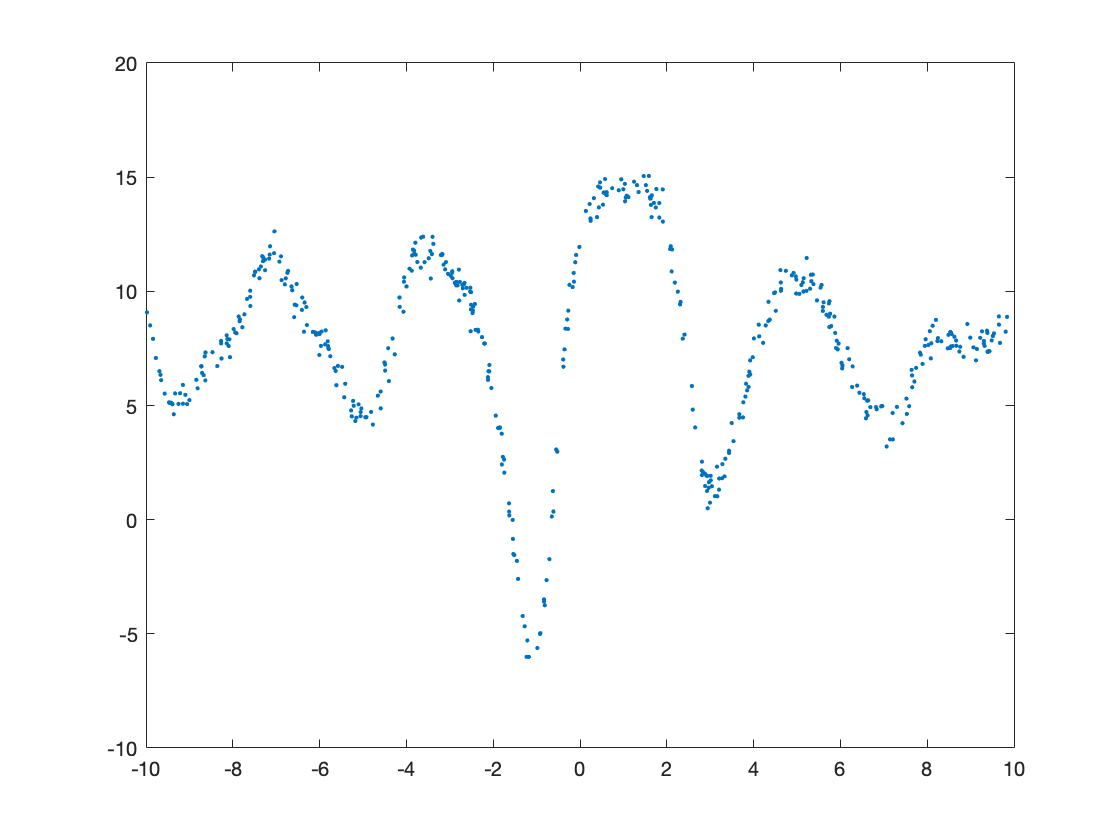

clear all;
m =500;
num = 10;
alpha =2*(rand(num,1));
U_train = 20*(rand(1,m)-0.5);
Y_train = NaN* zeros(1,m);
for k =1:m
    Y_train(k) = 0;
    for i = 1:num
        Y_train(k) = Y_train(k)+alpha(i)*(sin(alpha(i)*U_train(k)+cos(alpha(i)*U_train(k))))+ 0.5*rand(); 
    end
end
figure()
plot(U_train, Y_train, '.');

h = 50;
num_iter = 10;
radius = 0.5;
idl=ImplicitDeepLearning(U_train, Y_train, h, num_iter, 0 , radius); idl=idl.train; 

disp(idl.rmse)

    8.3519
    1.6862
    1.6864
    1.6866
    1.6868
    1.6870
    1.6872
    1.6874
    1.6876
    1.6878
    1.6880



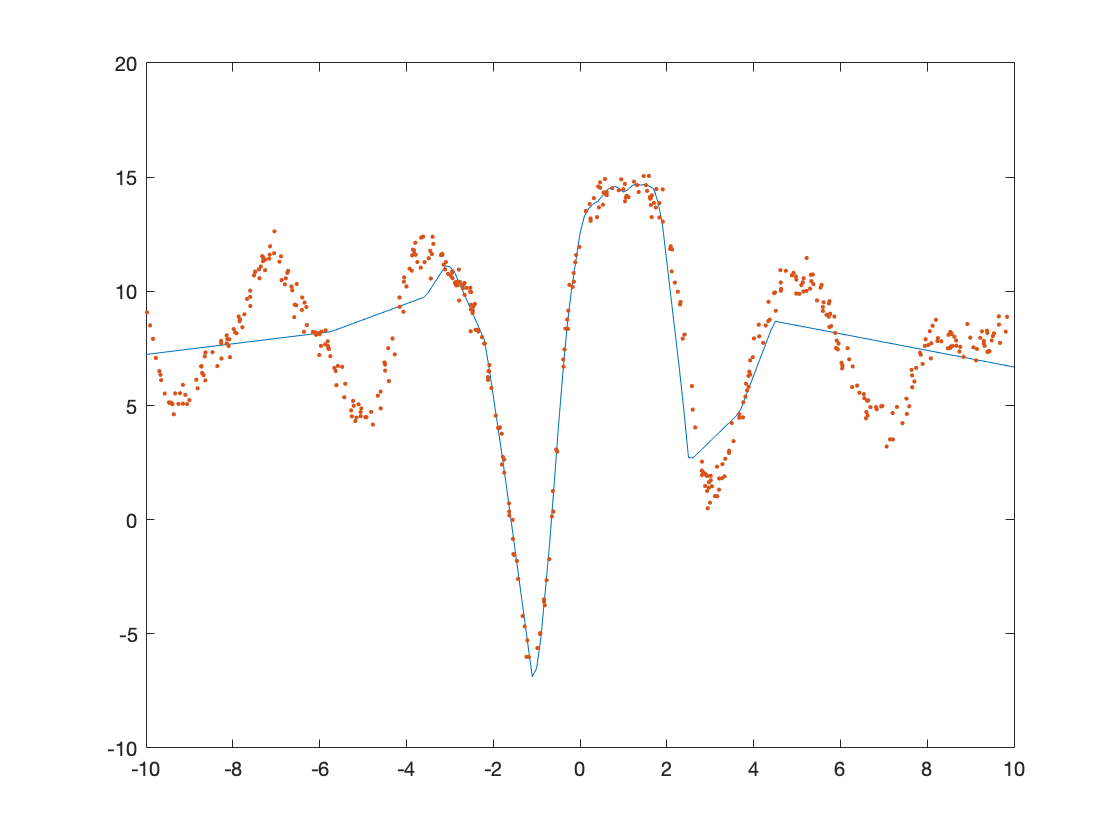

U = -10:0.1:10;
Y_prediction = idl.implicit_prediction(U);
figure()
plot(U, Y_prediction, '-')
hold on
plot(U_train, Y_train, '.');

tic
n = ceil(h/4);
layers = [
    sequenceInputLayer(1)
    fullyConnectedLayer(n)
    reluLayer 
    fullyConnectedLayer(n)
    reluLayer
    fullyConnectedLayer(n)
    reluLayer
    fullyConnectedLayer(n)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];

options = trainingOptions('adam','MaxEpochs',10^3,'MiniBatchSize',m/100,'InitialLearnRate',10^-3);
net = trainNetwork(U_train,Y_train,layers,options);

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |         6.65 |         22.1 |          0.0010 |
|      50 |          50 |       00:00:01 |         4.09 |          8.4 |          0.0010 |
|     100 |         100 |       00:00:02 |         2.99 |          4.5 |          0.0010 |
|     150 |         150 |       00:00:03 |         2.84 |          4.0 |          0.0010 |
|     200 |         200 |       00:00:04 |         2.75 |          3.8 |          0.0010 |
|     250 |         250 |       00:00:05 |         2.60 |          3.4 |          0.0010 |
|     300 |         300 |       00:00:06 |         2.45 |         

disp(toc)

   34.6984



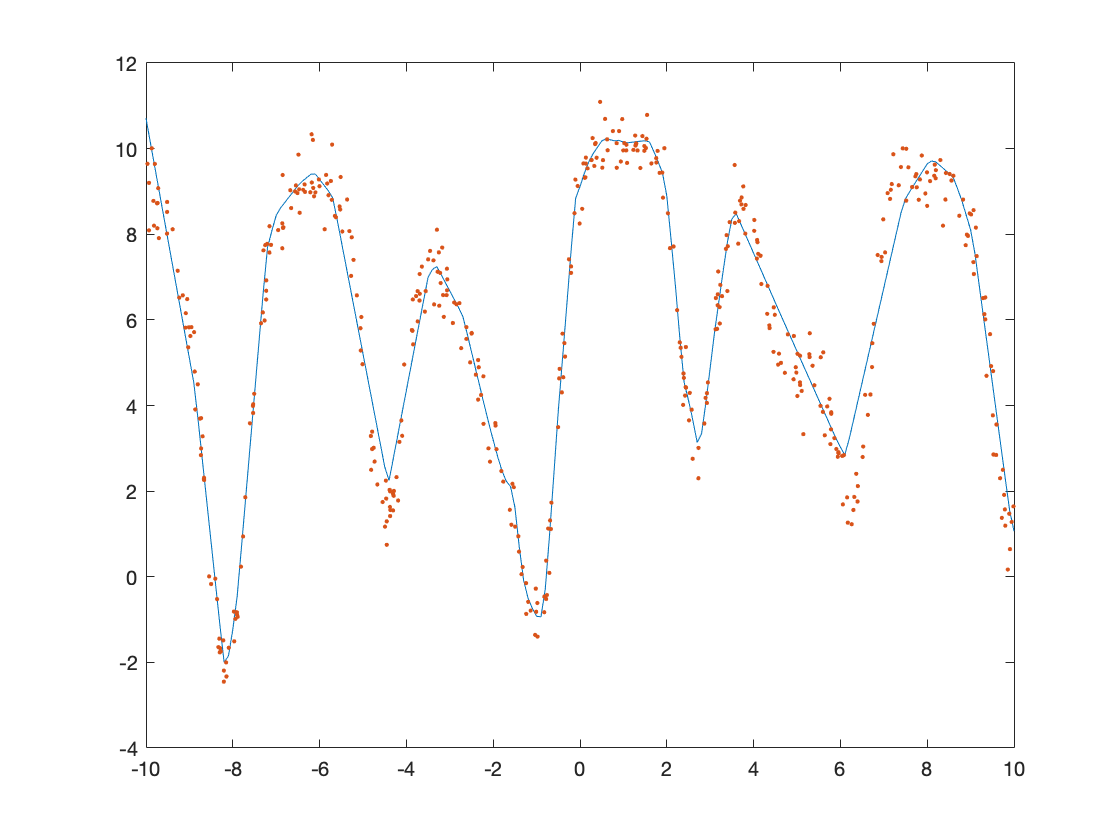

Y_prediction = predict(net,U);
figure()
plot(U, Y_prediction, '-')
hold on
plot(U_train, Y_train, '.');

[U_val_1,U_val_2] = meshgrid(0:0.5:10,0:0.5:10);
func = @(x,y) exp(sin(x)+sin(y))+0.01*y^2

func = function_handle with value:
    @(x,y)exp(sin(x)+sin(y))+0.01*y^2


Z = func(U_val_1,U_val_2);
figure
s=surf(U_val_1,U_val_2,Z)

s =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [21×21 double]
           YData: [21×21 double]
           ZData: [21×21 double]
           CData: [21×21 double]

  Show all properties


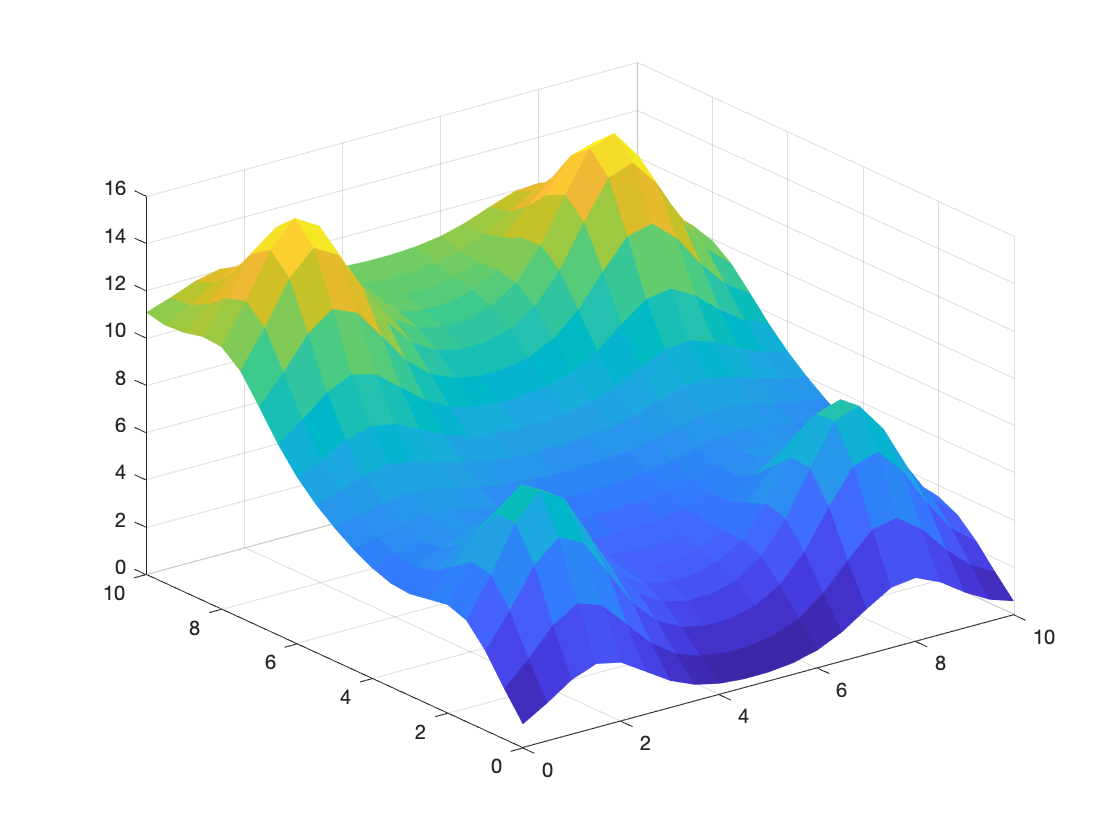

s.EdgeColor = 'none';

%zlim([-2.5 2.5])

% create data 
m = 2000;
U = NaN * ones(2,m);
Y = NaN * ones(1,m);
for i =1:m 
    U(:,i)=10*rand(2,1);
    Y(i)= func(U(1,i),U(2,i));
end

tic
h = 5000;
num_iter = 1;
radius = 0.5;
idl=ImplicitDeepLearning(U, Y, h, num_iter, 0 , radius); idl=idl.train; 
disp(toc)

   92.9098



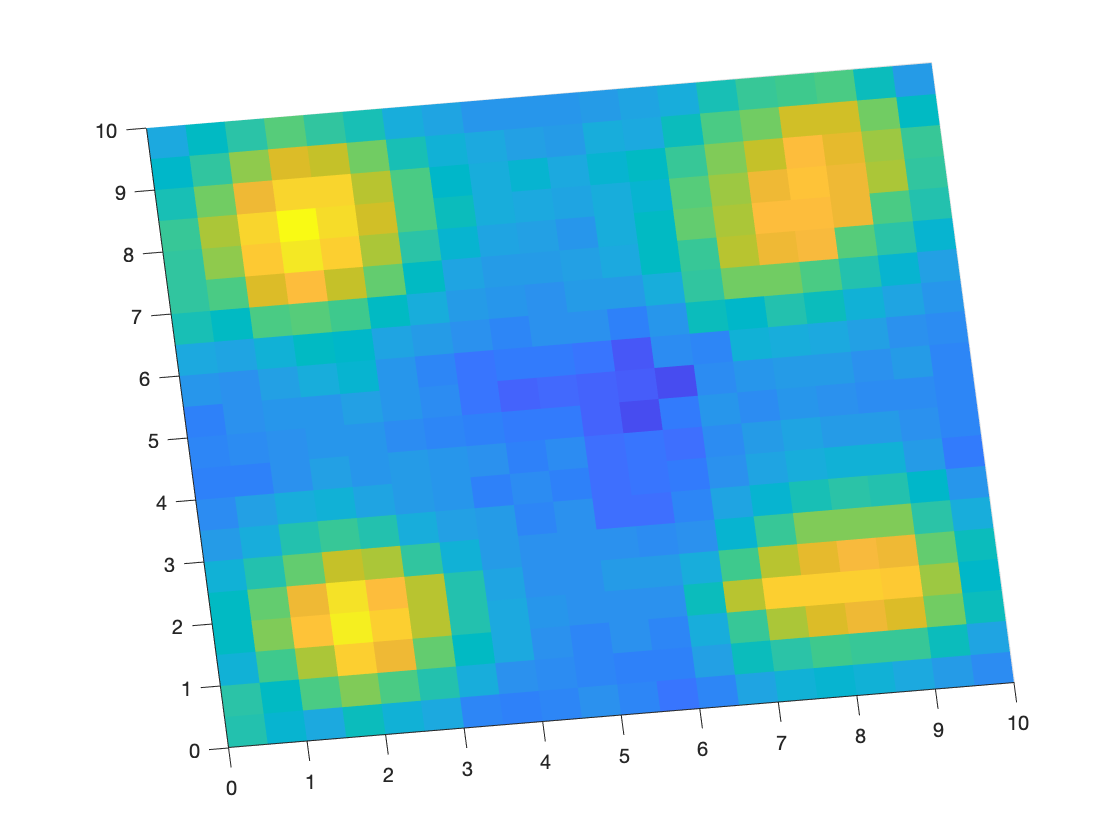

Y_prediction = NaN* zeros(size(U_val_1));
for k = 1:size(U_val_1,1)
    for j = 1:size(U_val_1,2)

        Y_prediction(k,j) = idl.implicit_prediction([U_val_1(k,j);U_val_2(k,j)]);

    end
end
figure
s=surf(U_val_1,U_val_2, Y_prediction);
s.EdgeColor = 'none';

%zlim([-2.5 2.5])

